# **Metoda złotego podziału**

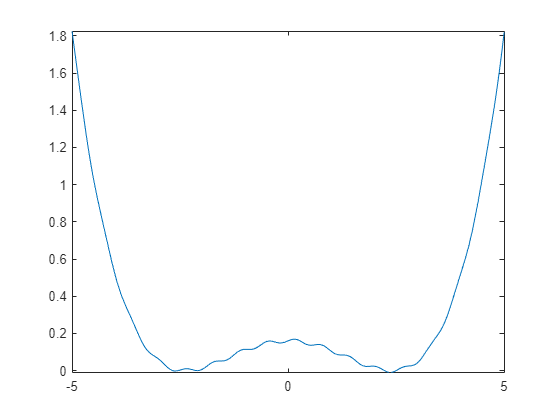

clearvars all; close all;
f = @(x) 0.01*sin(10*x)+(0.07*x.^2-0.4).^2;
px = [-10 -5 0 5 10]; py = [0.0001 -0.1 0 0.1 -0.0001]; stopien = 5; 
W = polyfit(px, py, stopien);
fx = @(x)(0.05*sin(1*x)+W(1)*x.^stopien+W(2)*x.^(stopien-1)+W(3)*x.^(stopien-2)+W(4)*x.^(stopien-3)+W(5)*x.^(stopien-4)+W(6)*x.^(stopien-5))*(0.001*sin(x/10))+0.000001*x;

x0 = -0.5;
r = 0.1;
alpha = 2;
epsi = 1e-4;
Nmax = 100;

fplot(f)

[left, right] = expansion(f, x0, r, alpha, Nmax)

left = -3.7000

right = -1.3000

[x, iteration] = golden_ratio(f, left, right, epsi, Nmax)

x = -2.0989

iteration = 22

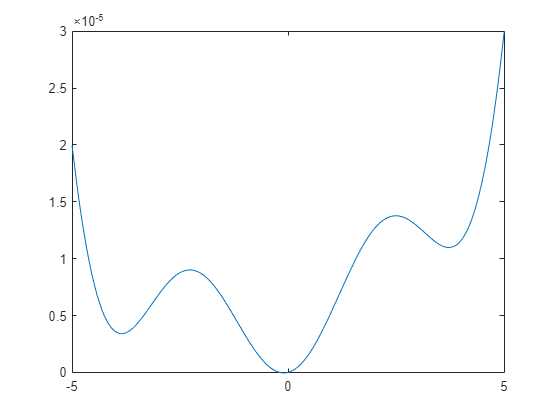


fplot(fx)

[left, right] = expansion(fx, x0, r, alpha, Nmax)

left = -0.3000

right = 0.3000

[x, iteration] = golden_ratio(fx, x0, x1, epsi, Nmax)

x = -0.1003

iteration = 20

clearvars all; close all;
px = [-10 -5 0 5 10]; py = [0.0001 -0.1 0 0.1 -0.0001]; stopien=5;
W = polyfit(px, py, stopien);
f= @(x) (0.001*sin(x/10)).*(0.05*sin(1*x)+W(1)*x.^stopien+W(2)*x.^(stopien-1)+W(3)*x.^(stopien-2)+W(4)*x.^(stopien-3)+W(5)*x.^(stopien-4)+W(6)*x.^(stopien-5))+0.000001*x;

epsi=0.05;
x0 = 20.9746;
x1 = 37.1929;

[x, iteration] = golden_ratio(f, x0, x1, epsi, Nmax)

x = 26.7583

iteration = 14

clearvars all; close all;
px = [-10 -5 0 5 10]; py = [0.0001 -0.1 0 0.1 -0.0001]; stopien=5;
W = polyfit(px, py, stopien);
f= @(x) (0.001*sin(x/10)).*(0.05*sin(1*x)+W(1)*x.^stopien+W(2)*x.^(stopien-1)+W(3)*x.^(stopien-2)+W(4)*x.^(stopien-3)+W(5)*x.^(stopien-4)+W(6)*x.^(stopien-5))+0.000001*x;

epsi=0.05;
x0 = -0.7086; 
x1 = 0.2406;

[x, iteration] = golden_ratio(f, x0, x1, epsi, Nmax)

x = -0.1056

iteration = 8